param;

% First Stage, Medium 1 


Bx1=(k^2-kx^2)*cos(kx*(xh-Nx)).*sin(ky*(yh-Ny))./(wFreq*Eo^2*Z0i(1)^2*Er_air);
By1=ky*kx*sin(kx*(xh-Nx)).*cos(ky*(yh-Ny))./(wFreq*Eo^2*Z0i(1)^2*Er_air);

% Bx1=-(k^2-kx^2)*cos(kx*(xh)).*sin(ky*(yh-Y2))./(wFreq*Eo*mu0*(sqrt(Z0i(1))));
% By1=ky*kx*sin(kx*(xh)).*cos(ky*(yh-Y2))./(wFreq*mu0*Eo*(sqrt(Z0i(1))));

% Second Stage, Medium 1
[Sx,H_sx,H_mx,H_ix,H_zx] = Sx(W,xh,h2);
[Sy,H_sy,H_my,H_iy,H_zy] = Sy(L,yh,h2);

for i=1:1:max(m)    
%   Axy1(:,1,i)=[(Sx(1,1,i)).*Bx1(i)+(Sy(1,2,i)).*By1(i);(Sx(2,1,i)).*Bx1(i)+(Sy(2,2,i)).*By1(i)];
    Axy1(:,:,i)=[(Sx(1,1,i)+Sx(2,1,i)).*Bx1(i)+Bx1o(i).*H_sx(i);(Sy(1,1,i)+Sy(2,1,i)).*By1(i)+By1o(i).*H_sy(i)]; 
   

end   



%Third Stage, Medium 1

Amn1=fmt(Axy1(1,:),Axy1(2,:),W,L,Qmn1);



%Fourth Stage, Medium 1
RC_1 = RC1(Er_air);

for i=1:1:max(m)
    Bmn1(:,:,i)=[RC_1(1,1,i).*Amn1(1,i);RC_1(2,2,i).*Amn1(2,i)];
end    



%Fith Stage, Medium 1

BXY1=ifmt(Bmn1,W,L,Qmn1);


% First Stage, Medium 2
Bx2=(k^2-kx^2)*cos(kx*(xh-Nx)).*sin(ky*(yh-Ny))./(wFreq*Eo^2*Z0i(2)^2*Er);
By2=ky*kx*sin(kx*(xh-Nx)).*cos(ky*(yh-Ny))./(wFreq*Eo^2*Z0i(2)^2*Er);

% Bx2=-(k^2-kx^2)*cos((pi/(W))*(xh)).*sin((pi/(L))*(yh-Y2))./(wFreq*Eo*mu0*(sqrt(Z0i(2))));
% By2=ky*kx*sin((pi/(W))*(xh)).*cos((pi/(L))*(yh-Y2))./(wFreq*mu0*Eo*(sqrt(Z0i(2))));


% Second Stage, Medium 2


for i=1:1:max(m)     
%     Axy2(:,1,i)=[(Sx(1,1,i)).*Bx2(i)+(Sy(1,2,i)).*By2(i);(Sx(2,1,i)).*Bx2(i)+(Sy(2,2,i)).*By2(i)];
      Axy2(:,:,i)=[(Sx(1,2,i)+Sx(2,2,i)).*Bx2(i)+Bx2o(i).*H_sx(i);(Sy(1,2,i)+Sy(2,2,i)).*By2(i)+By2o(i).*H_sy(i)];
      
end



%Third Stage, Medium 2
Amn2=fmt(Axy2(1,:),Axy2(2,:),W,L,Qmn2);

%Fourth Stage, Medium 2
RC_2 = RC2(Er);
for i=1:1:max(m)    
    Bmn2(:,:,i)=[RC_2(1,1,i)*Amn2(1,i);RC_2(2,2,i).*Amn2(2,i)];
end


%Fith Stage, Medium 2

BXY2=ifmt(Bmn2,W,L,Qmn2);


%Final Stage, Calculations from all mediums

ea1=sqrt(Z0i(1)).*Axy1(1,:)+sqrt(Z0i(1)).*Axy1(2,:);
ea2=sqrt(Z0i(2)).*Axy2(1,:)+sqrt(Z0i(2)).*Axy2(2,:);

eb1=sqrt(Z0i(1)).*BXY1(1,:)+sqrt(Z0i(1)).*BXY1(2,:);
eb2=sqrt(Z0i(2)).*BXY2(1,:)+sqrt(Z0i(2)).*BXY2(2,:);

ja1=Axy1(1,:)/sqrt(Z0i(1))+Axy1(2,:)/sqrt(Z0i(1));
ja2=Axy2(1,:)/sqrt(Z0i(2))+Axy2(2,:)/sqrt(Z0i(2));

jb1=BXY1(1,:)/sqrt(Z0i(1))+BXY1(2,:)/sqrt(Z0i(1));
jb2=BXY2(1,:)/sqrt(Z0i(2))+BXY2(2,:)/sqrt(Z0i(2));


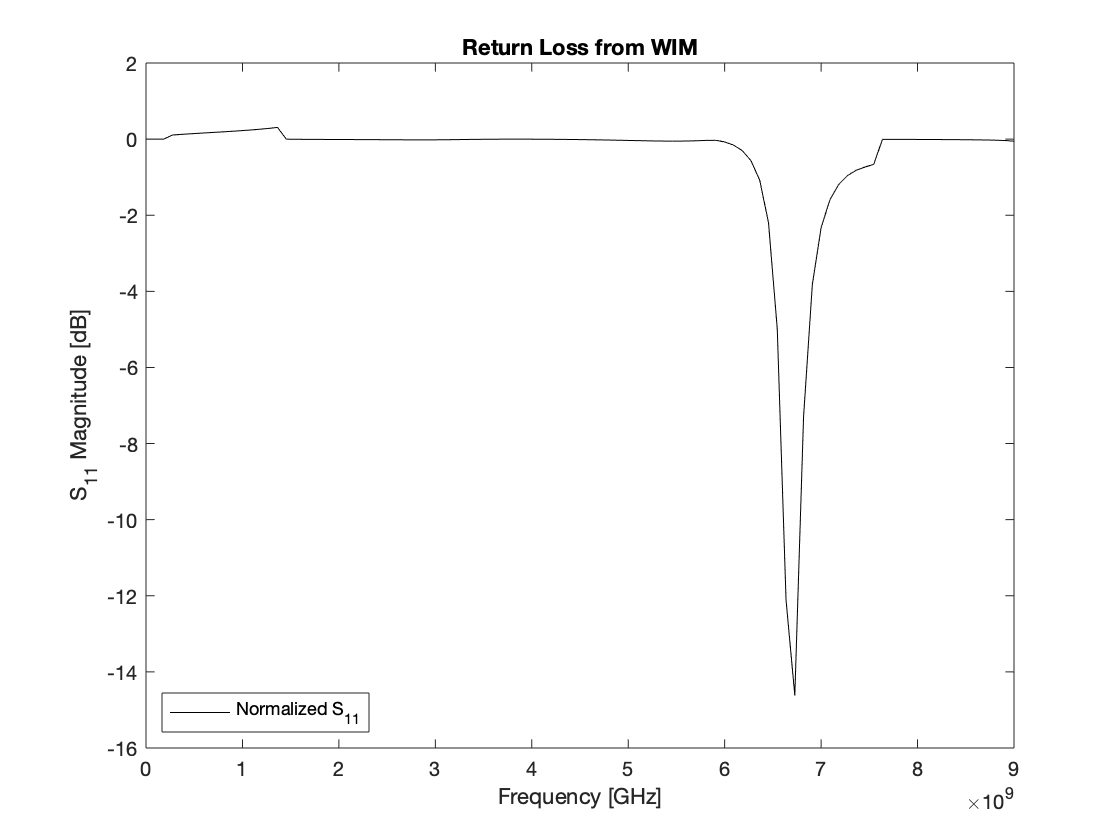

n_ea=sqrt(abs(ea1).^2+abs(ea2).^2);
n_eb=sqrt(abs(eb1).^2+abs(eb2).^2);
n_ja=sqrt(abs(ja1).^2+abs(ja2).^2);
n_jb=sqrt(abs(jb1).^2+abs(jb2).^2);

% n_ea=sqrt(real(ea1).^2+real(ea2).^2);
% n_eb=sqrt(real(eb1).^2+real(eb2).^2);
% n_ja=sqrt(real(ja1).^2+real(ja2).^2);
% n_jb=sqrt(real(jb1).^2+real(jb2).^2);






Exy1=(ea1+ea2)./n_ea+(eb1+eb2)./n_eb;
Jxy1=(ja1+ja2)./n_ja-(jb1+jb2)./n_jb;
Exy2=(ea1+ea2)+(eb1+eb2);
Jxy2=(ja1+ja2)-(jb1+jb2);


Z1=Exy1./Jxy1;
%Rcoef=(1-Z/Z0)./(1+Z/Z0);
Rcoef1=(Z0-Z1)./(Z1+Z0);
RL1=20*log(abs(Rcoef1));

Z2=Exy2./Jxy2;
Rcoef2=(Z0-Z2)./(Z2+Z0);
RL2=20*log(abs(Rcoef2));

fl=linspace(0,9e9,T);
plot(fl,real(RL1),'k')


legend({'Normalized S_{11}'},'Location','South West')
% plot(fl,real(RL1),'k')
% legend({'S_{11}'},'Location','South West')
title('Return Loss from WIM')
xlabel('Frequency [GHz]')
ylabel('S_{11} Magnitude [dB]')